# Condenser Microphone

This example shows a general model of a condenser microphone. Condenser microphones are common technology used in measurement microphone as well as commercial devices such as cell phones and headphones. They are also the foundation of semi-conductor receivers such as MEMS microphones. Specifically, this example models the response of a pressure microphone Type 4134 from B&K. This model breaks down the details of a typical condenser microphone. However, a composite `Condenser Microphone` block is included within the acoustic domain library.

## Open Model

Open condenser microphone model.

model = 'CondenserMic';
open_system(model);

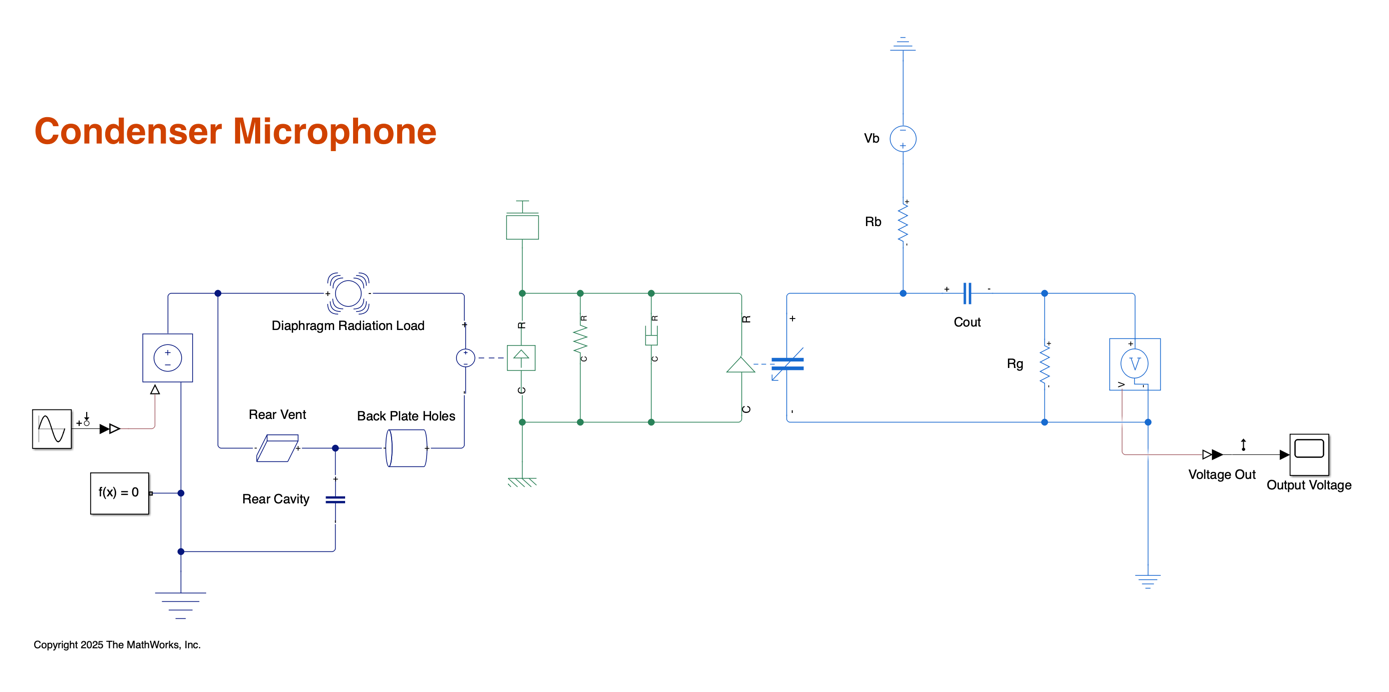

The incident pressure is met by the radiation loading on the membrane, contributed from the particles on the surface. The radiation loading is modeled as the radiation impedance from a spherical source given the following configuration:

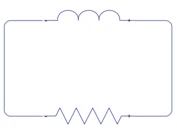

The inductor represents the mass loading and the resistor represents the damping on the membrane. The component values can be calculated as follows:


$$M_{rad} =\frac{\rho a}{4\pi a^2 }$$



$$R_{rad} =\frac{\rho c}{4\pi a^2 }$$


Where:

- $\rho$ is the density of air$1\ldotp 21kg/m^3$

- $c$ is the sound speed in air $343m/s$

- $a$ is the radius of the membrane

The incident pressure is then coupled into the mechanical domain. The coupling between the acoustic and mechanical domain is through an area transformer. The coupling relationship of the variables are given by:


$$p=\frac{F}{A}$$



$$U=vA$$


Where:

- $p$, the potential variable, is the pressure in $N/m^2$

- $U$, the flow variable, is the volume velocity in $m^3 /s$

- $A$ is the surface area of the membrane

## Calculate the Frequency Response 

The condenser microphone is a dynamic device that is difficult for linearized analysis. The membrane is modeled as a single degree-of-freedom mass-spring system. Note that the spring rate includes stiffness from the material properties and the pre-stretch stresses that hold the membrane in place.

A layer of electrodes is distributed on the back plate that creates an electric field between the back plate and the membrane. The separation between the two forms a 2-plate capacitor, and the dynamic capacitance can be calculated by:


$$C=\frac{\epsilon_0 A}{h_{gap} -x}$$


Where:

- $\epsilon_0$ is the permittivity in vacuum $8\ldotp 85\times 10^{-12} F/m$

- $h_{gap}$ is the separation distance

- $A$ is the surface area of the back plate

- $x$ is the dynamic displacement of the membrane

As the power supply `Vb` is turned on, it takes a certain amount of time for the capacitor to be fully charged. While the capacitance is charged, the diaphragm motion is also going through a transient state where it is displaced due to the electrical field in the gap.

To properly plot the steady state response, the signals have to be windowed to exclude the initial transients. Thus, a series of frequency point for the analysis are defined and sweep though the parameter defined in the model, which is the input signal frequency.  Use the function `setVariable `to set the parameter `f_in`, which is already defined within the model.

Since the model settings do not change (other than the frequency) as it runs through each frequency response, the function `parsim` can be used to parallel simulate the model without rerun the model manually. 

load("FrequencyList.mat");              % load list of frequency to run in the model

for i = 1:length(f_in)
    
    % define input parameter in the model to be swept
    in(i) = Simulink.SimulationInput(model);
    in(i) = in(i).setVariable('f_in',f_in(i));

end

out = parsim(in, 'ShowSimulationManager', 'off')         % use parsim to run model in parallel

[04-May-2025 13:28:00] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 2 workers.
[04-May-2025 13:28:21] Starting Simulink on parallel workers...
[04-May-2025 13:28:26] Configuring simulation cache folder on parallel workers...
[04-May-2025 13:28:26] Loading model on parallel workers...
[04-May-2025 13:28:34] Running simulations...
[04-May-2025 13:29:03] Completed 1 of 39 simulation runs
[04-May-2025 13:29:03] Received simulation output (size: 5.50 MB) for run 1 from parallel worker.
[04-May-2025 13:29:03] Completed 2 of 39 simulation runs
[04-May-2025 13:29:03] Received simulation output (size: 5.50 MB) for run 2 from parallel worker.
[04-May-2025 13:29:08] Completed 3 of 39 simulation runs
[04-May-2025 13:29:08] Received simulation output (size: 5.50 MB) for run 3 from parallel worker.
[04-May-2025 13:29:08] Completed 4 of 39 simulation runs
[04-May-2025 13:29:08] Received simulation outp

out = 1x39 Simulink.SimulationOutput array



## Plot the Sensitivity

Once the parallel simulation is completed, `parsim` generates the results of each run, which corresponse to each individual frequency. The time series signal is extracted and windowed between 4 and 5 seconds where the system transient has already settled.

Setting the time Information

t_out = out(1,1).tout(:);           % extract time sequence
start_t = 4;                        % window starting time
end_t = 5;                          % window end time
idx1 = find(t_out == start_t);      % starting time index
ind2 = find(t_out == end_t);        % ending time index
win_time = t_out(idx1:ind2);        % extract time
win_time = win_time(1:end - 1);     % windowed time vector 

The voltage from the output results are also extraced corresponse to the windowed time.  

 Extract Voltage

v_out = nan(length(f_in), length(win_time));           % preallocate pressure matrix for each frequency time series

for idx = 1:length(f_in)

    v = out(1,idx).vout.signals.values(:);
    wv = v(idx1:ind2 - 1);    % windowed signal
    v_out(idx,:) = wv;

end

The Fourier Transform is performed to obtain the spectral content of the extracted votlage signal. Since each individual simlation only contain one single frequency incident, the maximum values of the FFT curves are the steady state response at each frequency. The steady state responses of each given frequency (the maximum values) are collected and plot in dB reference to 1V/Pa.

Do the FFT

L = size(v_out, 2);       % signal length
v_amp = nan(length(f_in), 1);             % preallocate true pressure amplitude for each frequency after FFT calculation

for idx = 1:length(f_in)

    v_fft = fft(v_out(idx, :));
    v_fft = v_fft(1:end/2 + 1);
    v_amp(idx) = max(2*abs(v_fft)/L);             % calculate true amplitude and store into matrix

end

Plot the results.

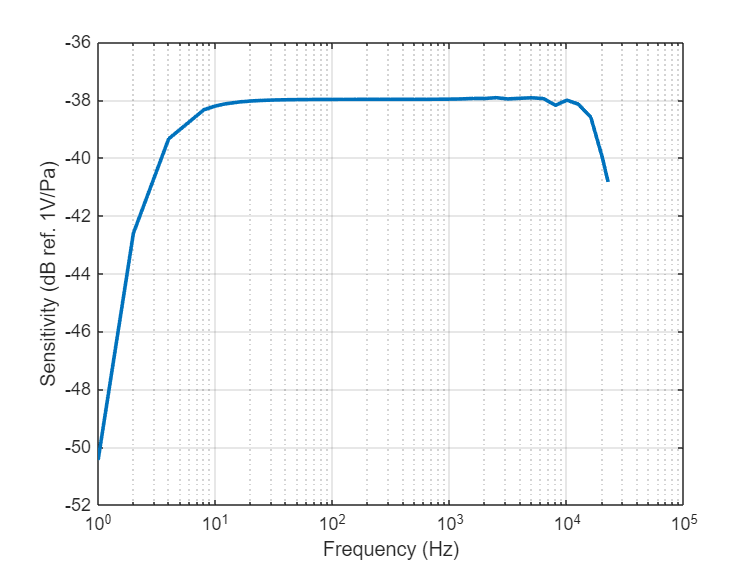

figure(1)
semilogx(f_in, 20*log10(v_amp), "LineWidth", 2);
grid on
hold on
xlabel("Frequency (Hz)");
ylabel("Sensitivity (dB ref. 1V/Pa)");

## Reduce the Rear Cavity

On the rear side of the membrane, the air in the gap flows through the holes and slot into the rear cavity. The acoustic elements of the air gap are eliminated for simplicity. The compliance in the air gap is negligible compared to the compliance of the rear cavity. The air mass can be modeled as multiple "air cells" from the holes on the back plate.

The air resistance depends on the boundary conditions around the gap cavity and the velocity profile of the diaphragm. The boundary is in between a closed and open condition.The velocity profile of the diaphragm is not a perfect piston motion as it is fixed around the edge and more curvature towards the center. For this model, the diaphragm displacement is assumed to be piston motion.

The holes on the back plate can be seen as small tubes with identical dimensions. Small tubes can be modeled as an inductor and resistor connected in series. For multiple holes with identical dimensions, each hole is stacked in parallel.

The air mass in the holes:


$$M_a =\frac{4\rho l_{holes} }{3A_{holes} N_{holes} }$$


The air resistance: 


$$R_a =\frac{8\pi \rho \nu l_{holes} }{A_{holes}^2 N_{holes} }$$


where:

- $\rho$ is the density of air $1\ldotp 21kg/m^3$

- $\nu$ is the viscosity of air $15\ldotp 68\times 10^{-6} m^2 /s$

- $l_{holes}$ is the length of the holes.

- $A_{holes}$ is the opening area of the holes.

- $N_{holes}$ is the number of holes.

For rectangular slot:


$$M_a =\frac{1\ldotp 2\rho l_{slot} }{N_{slot} w_{slot} h_{slot} }$$



$$R_a =\frac{12\rho \nu l_{slot} }{N_{slot} w_{slot} h_{slot}^3 }$$


where:

- $l_{slot}$ is the length of the slot.

- $w_{slot}$ is the width of the slot.

- $h_{slot}$ is the hieght of the slot.

- $N_{slot}$ is the number of slot.

The rear cavity can be simplified as a single compliance, which is represented as a capacitor. The component value with a certain volume $V$ is given by the following equation:


$$C=\frac{\;V}{\;\rho c^{2\;} }$$


where $\rho \;$is the air density and $c$ is the speed of sound in air

By reducing the rear cavity, the complaince is decreased. Decreasing compliance leads to increase in the stiffness which is applied on the diaphragm. As the stiffer rear cavity opposes the diaphragm motion, the produced voltage is reduced and resulting lower sensitivity.

path = [model,'/Rear Cavity'];
set_param(path,'c', '0.1*Vb/(rho*c^2)');         % set parameter to decrease the rear cavity by a factor of 0.1
save_system(model);

out = parsim(in, 'ShowSimulationManager', 'off')         % use parsim to rum model in parallel

[04-May-2025 13:31:16] Checking for availability of parallel pool...
[04-May-2025 13:31:16] Starting Simulink on parallel workers...
[04-May-2025 13:31:16] Configuring simulation cache folder on parallel workers...
[04-May-2025 13:31:16] Loading model on parallel workers...
[04-May-2025 13:31:18] Running simulations...
[04-May-2025 13:31:23] Completed 1 of 39 simulation runs
[04-May-2025 13:31:23] Received simulation output (size: 5.50 MB) for run 1 from parallel worker.
[04-May-2025 13:31:23] Completed 2 of 39 simulation runs
[04-May-2025 13:31:23] Received simulation output (size: 5.50 MB) for run 2 from parallel worker.
[04-May-2025 13:31:26] Completed 3 of 39 simulation runs
[04-May-2025 13:31:26] Received simulation output (size: 5.50 MB) for run 3 from parallel worker.
[04-May-2025 13:31:26] Completed 4 of 39 simulation runs
[04-May-2025 13:31:26] Received simulation output (size: 5.50 MB) for run 4 from parallel worker.
[04-May-2025 13:31:30] Completed 5 of 39 simulation runs
[0

out = 1x39 Simulink.SimulationOutput array



 Extract Voltage

v_out = nan(length(f_in), length(win_time));           % preallocate pressure matrix for each frequency time series

for idx = 1:length(f_in)

    v = out(1,idx).vout.signals.values(:);
    wv = v(idx1:ind2 - 1);    % windowed signal
    v_out(idx,:) = wv;

end

Perform the FFT.

L = size(v_out, 2);       % signal length
v_amp = nan(length(f_in), 1);             % preallocate true pressure amplitude for each frequency after FFT calculation

for idx = 1:length(f_in)

    v_fft = fft(v_out(idx, :));
    v_fft = v_fft(1:end/2 + 1);
    v_amp(idx) = max(2*abs(v_fft)/L);             % calculate true amplitude and store into matrix

end

Plot the results

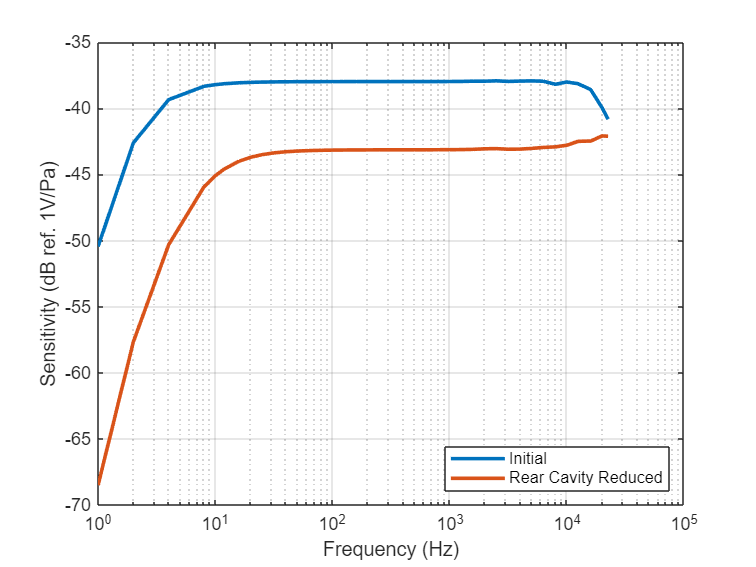

figure(1)
semilogx(f_in, 20*log10(v_amp), "LineWidth", 2);
grid on
hold on
legend("Initial", "Rear Cavity Reduced", "Location", "southeast");
xlabel("Frequency (Hz)");
ylabel("Sensitivity (dB ref. 1V/Pa)");

set_param(path,'c', 'Vb/(rho*c^2)');         % Reset rear cavity value
save_system(model);

## Reduce the Air Gap

The charges on the back plate exter an attraction force on the membrane. As the membrane is displaced by the incident pressure, the separation changes. The attraction force and the capacitance also change along with the dynamic motion. The attraction force is given by:


$$F_0 =\frac{\epsilon_0 A(V_b +e)^2 }{2(h_{gap} -x)^2 }$$


Where:

- $V_b$ is bias voltage 

- $e$ is the dynamic voltage induced by the membrane motion

Note that the attraction force will give the membrane an initial displacement once it is charged. It is inversely squared proportional to the diaphragm displacement opposing the input pressure. Increasing the bias voltage can increase the microphone sensitivity. However, passing certain threshold, the diaphragm will collapse and stuck on the back plate due to the attraction force.

The distributed charges will vary along with the motion of the diaphragm and thus generates the dynamic voltage output. The total output voltage is the sum of the bias voltage and the dynamic voltage. A small capacitor is placed at the output to filter the DC voltage.

As the gap between the back plate and diaphragm decreased, the electric field or the attraction force between them increases. With the same amount of charges disctributed across the area, the force within the gap is inversly proportional to the separation. Increasing in force also leads to the increase in the overall sensitivity.

path = [model,'/Variable Gap Capacitor'];
set_param(path,'d', '0.75*h_gap');         % set parameter to decrease the ari gap by a factor of 0.75
save_system(model);

out = parsim(in, 'ShowSimulationManager', 'off')         % use parsim to rum model in parallel

[04-May-2025 13:33:13] Checking for availability of parallel pool...
[04-May-2025 13:33:13] Starting Simulink on parallel workers...
[04-May-2025 13:33:13] Configuring simulation cache folder on parallel workers...
[04-May-2025 13:33:13] Loading model on parallel workers...
[04-May-2025 13:33:15] Running simulations...
[04-May-2025 13:33:21] Completed 1 of 39 simulation runs
[04-May-2025 13:33:21] Received simulation output (size: 5.50 MB) for run 1 from parallel worker.
[04-May-2025 13:33:22] Completed 2 of 39 simulation runs
[04-May-2025 13:33:22] Received simulation output (size: 5.50 MB) for run 2 from parallel worker.
[04-May-2025 13:33:27] Completed 3 of 39 simulation runs
[04-May-2025 13:33:27] Received simulation output (size: 5.50 MB) for run 3 from parallel worker.
[04-May-2025 13:33:27] Completed 4 of 39 simulation runs
[04-May-2025 13:33:27] Received simulation output (size: 5.50 MB) for run 4 from parallel worker.
[04-May-2025 13:33:32] Completed 5 of 39 simulation runs
[0

out = 1x39 Simulink.SimulationOutput array



Extract Voltage

v_out = nan(length(f_in), length(win_time));           % preallocate pressure matrix for each frequency time series

for idx = 1:length(f_in)

    v = out(1,idx).vout.signals.values(:);
    wv = v(idx1:ind2 - 1);    % windowed signal
    v_out(idx,:) = wv;

end

Perform FFT

L = size(v_out, 2);       % signal length
v_amp = nan(length(f_in), 1);             % preallocate true pressure amplitude for each frequency after FFT calculation

for idx = 1:length(f_in)

    v_fft = fft(v_out(idx, :));
    v_fft = v_fft(1:end/2 + 1);
    v_amp(idx) = max(2*abs(v_fft)/L);             % calculate true amplitude and store into matrix

end

Plot the results.

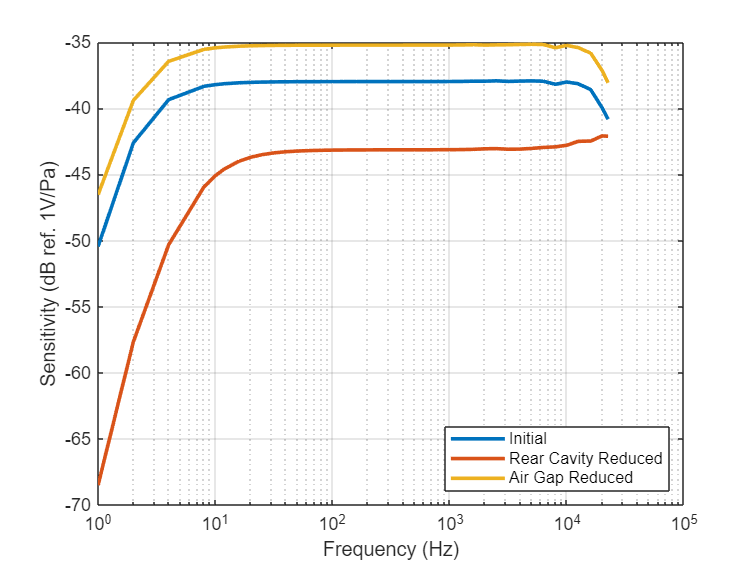

figure(1)
semilogx(f_in, 20*log10(v_amp), "LineWidth", 2);
grid on
hold on
legend("Initial", "Rear Cavity Reduced", "Air Gap Reduced", "Location", "southeast");
xlabel("Frequency (Hz)");
ylabel("Sensitivity (dB ref. 1V/Pa)");

set_param(path,'d', 'h_gap');         % Reset air gap value
save_system(model);

## Increase the Rear Vent Opening 

The rear vent acts like a pressure release path to equalize the rear cavity pressure and the barometric pressure, which can be modeled as a rectangular slot or cylindrical tube.

Increasing the rear vent opening reduces the overall impedance along the pathway, especially for low frequencies. It is essentially introducing more "leakage" to the ambient environment. As the opening increases, it is expected that there will be more sensitivity losses in low frequencies.

path = [model,'/Rear Vent'];
set_param(path,'w', 'l_vent*2');         % set parameter to increase the rear vent width by a factor of 2
set_param(path,'h', 'w_vent*2');         % set parameter to increase the rear vent height by a factor of 2
save_system(model);

out = parsim(in, 'ShowSimulationManager', 'off')         % use parsim to rum model in parallel

[04-May-2025 13:36:18] Checking for availability of parallel pool...
[04-May-2025 13:36:18] Starting Simulink on parallel workers...
[04-May-2025 13:36:19] Configuring simulation cache folder on parallel workers...
[04-May-2025 13:36:19] Loading model on parallel workers...
[04-May-2025 13:36:20] Running simulations...
[04-May-2025 13:36:31] Completed 1 of 39 simulation runs
[04-May-2025 13:36:31] Received simulation output (size: 5.50 MB) for run 1 from parallel worker.
[04-May-2025 13:36:31] Completed 2 of 39 simulation runs
[04-May-2025 13:36:31] Received simulation output (size: 5.50 MB) for run 2 from parallel worker.
[04-May-2025 13:36:38] Completed 3 of 39 simulation runs
[04-May-2025 13:36:38] Received simulation output (size: 5.50 MB) for run 3 from parallel worker.
[04-May-2025 13:36:38] Completed 4 of 39 simulation runs
[04-May-2025 13:36:38] Received simulation output (size: 5.50 MB) for run 4 from parallel worker.
[04-May-2025 13:36:44] Completed 5 of 39 simulation runs
[0

out = 1x39 Simulink.SimulationOutput array



Extract Voltage

v_out = nan(length(f_in), length(win_time));           % preallocate pressure matrix for each frequency time series

for idx = 1:length(f_in)

    v = out(1,idx).vout.signals.values(:);
    wv = v(idx1:ind2 - 1);    % windowed signal
    v_out(idx,:) = wv;

end

Perform FFT

L = size(v_out, 2);       % signal length
v_amp = nan(length(f_in), 1);             % preallocate true pressure amplitude for each frequency after FFT calculation

for idx = 1:length(f_in)

    v_fft = fft(v_out(idx, :));
    v_fft = v_fft(1:end/2 + 1);
    v_amp(idx) = max(2*abs(v_fft)/L);             % calculate true amplitude and store into matrix

end

Plot the results.

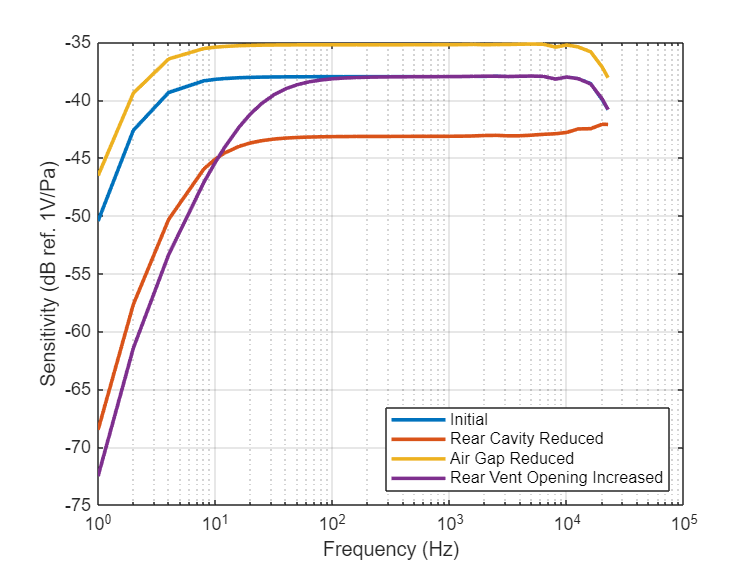

figure(1)
semilogx(f_in, 20*log10(v_amp), "LineWidth", 2);
grid on
hold on
legend("Initial", "Rear Cavity Reduced", "Air Gap Reduced", "Rear Vent Opening Increased", ...
    "Location", "southeast");
xlabel("Frequency (Hz)");
ylabel("Sensitivity (dB ref. 1V/Pa)");

set_param(path,'w', 'l_vent');         % reset rear vent width value
set_param(path,'h', 'w_vent');         % reset rear vent height value
save_system(model);

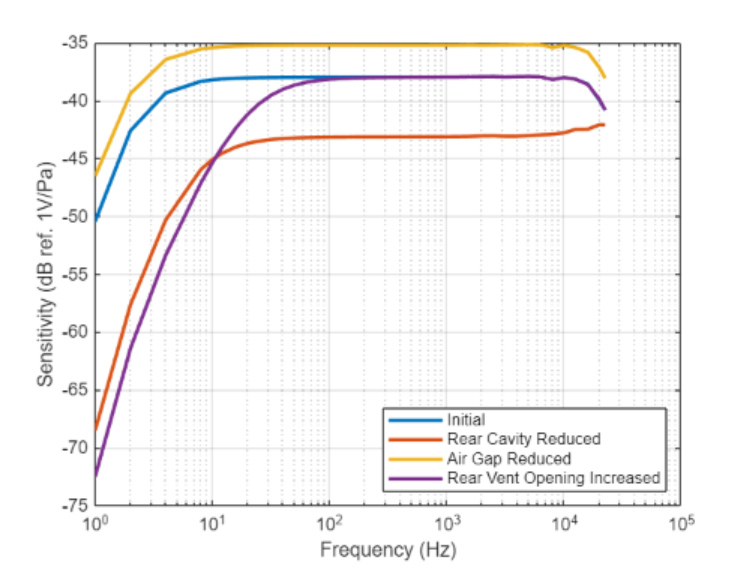

Close the system.

bdclose(model)

## Reference 

- Josué Esteves & Libor Rufer & Didace Ekeom & Skandar Basrour. (2017). Lumped-Parameters Equivalent Circuit For Condenser Microphones Modeling. The Journal of the Acoustical Society of America. 142. 10.1121/1.5006905. 

- Allan J. Zuckerwar. (1978). Theoretical Response Of Condenser Microphones. The Journal of the Acoustical Society of America. 64. 10.1121/1.382112.

*Copyright 2025 The MathWorks, Inc.*